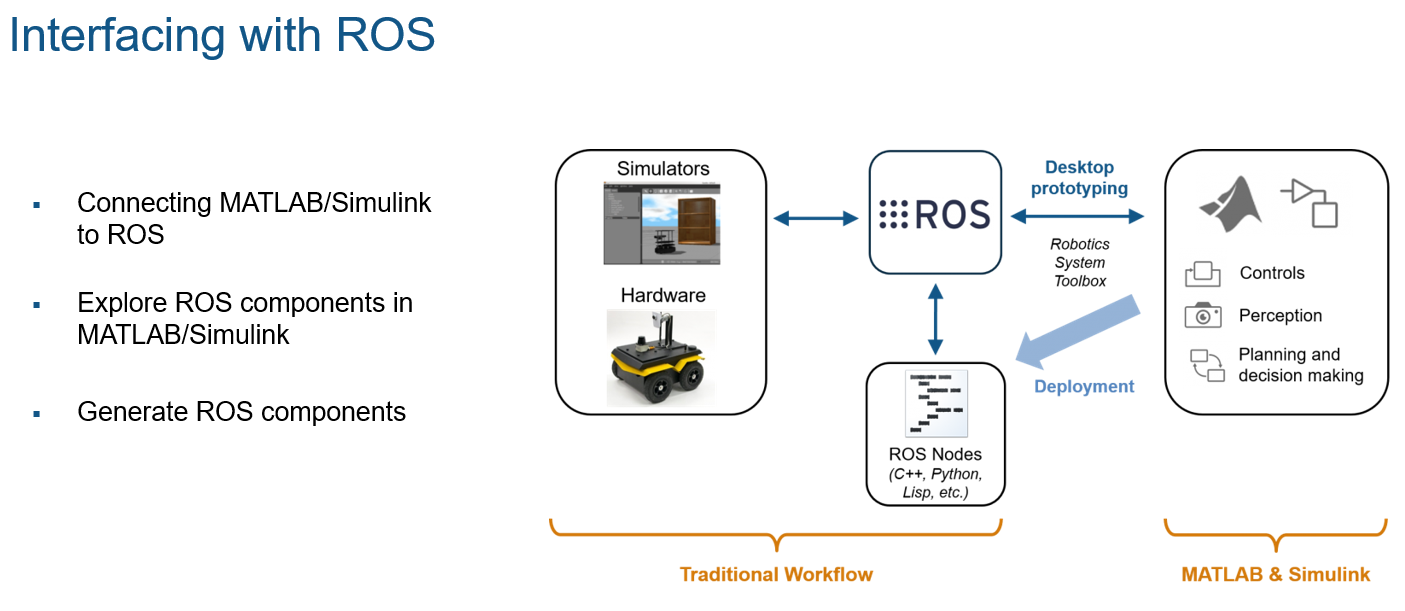

## Connecting MATLAB/Simulink to ROS

`rosinit` starts the global ROS node with a default MATLAB® name and tries to connect to a ROS master running on `localhost` and port `11311`. If the global ROS node cannot connect to the ROS master, `rosinit` also starts a ROS core in MATLAB, which consists of a ROS master, a ROS parameter server, and a rosout logging node.

rosshutdown
rosinit 192.168.137.134

Initializing global node /matlab_global_node_69208 with NodeURI http://192.168.137.1:56567/


## Explore ROS components in MATLAB/Simulink 

`rosnode list` returns a list of all nodes registered on the ROS network. Use these nodes to exchange data between MATLAB® and the ROS network. `rostopic list` returns a list of ROS topics from the ROS master.

rosnode list

/better_odom
/gazebo
/gazebo_gui
/gazebo_odometry_node
/matlab_global_node_69208
/racecar/controller_manager
/racecarsystem_nmr_deployment_node
/robot_state_publisher
/rosout
/servo_commands
/testimufilter_node
/vesc/high_level/ackermann_cmd_mux
/vesc/high_level/ackermann_cmd_mux_nodelet_manager
/vesc/low_level/ackermann_cmd_mux
/vesc/low_level/ackermann_cmd_mux_nodelet_manager
/vesc/mux_chainer
/vesc/mux_topic_backward_compat_navigation
/vesc/mux_topic_backward_compat_safety
/vesc/mux_topic_backward_compat_teleop


rostopic list

/camera/zed/parameter_descriptions                                          
/camera/zed/parameter_updates                                               
/camera/zed/rgb/camera_info                                                 
/camera/zed/rgb/image_rect_color                                            
/camera/zed/rgb/image_rect_color/compressed                                 
/camera/zed/rgb/image_rect_color/compressed/parameter_descriptions          
/camera/zed/rgb/image_rect_color/compressed/parameter_updates               
/camera/zed/rgb/image_rect_color/compressedDepth                            
/camera/zed/rgb/image_rect_color/compressedDepth/parameter_descriptions     
/camera/zed/rgb/image_rect_color/compressedDepth/parameter_updates          
/camera/zed/rgb/image_rect_color/theora                                     
/camera/zed/rgb/image_rect_color/theora/parameter_descriptions              
/camera/zed/rgb/image_rect_color/theora/parameter_updates                   

## Debug ROS components in MATLAB/Simulink 

`rostopic echo` [`topicname`](https://www.mathworks.com/help/ros/ref/rostopic.html#bupf5_j_14-topicname) returns the messages being sent from the ROS master about a specific topic, `topicname`. 

`rostopic info` [`topicname`](https://www.mathworks.com/help/ros/ref/rostopic.html#bupf5_j_14-topicname) returns the message type, publishers, and subscribers for a specific topic, `topicname`. 

`rostopic type` [`topicname`](https://www.mathworks.com/help/ros/ref/rostopic.html#bupf5_j_14-topicname) returns the message type for a specific topic.

rostopic type /scan

sensor_msgs/LaserScan


rostopic info /clock

Type: rosgraph_msgs/Clock
 
Publishers:
* /gazebo (http://192.168.137.134:37291/)
 
Subscribers:
* /racecarsystem_nmr_deployment_node (http://192.168.137.134:33425/)
* /vesc/low_level/ackermann_cmd_mux_nodelet_manager (http://192.168.137.134:38279/)
* /testimufilter_node (http://192.168.137.134:41343/)
* /vesc/mux_topic_backward_compat_teleop (http://192.168.137.134:36491/)
* /vesc/high_level/ackermann_cmd_mux_nodelet_manager (http://192.168.137.134:39157/)
* /better_odom (http://192.168.137.134:39771/)
* /servo_commands (http://192.168.137.134:39383/)
* /vesc/mux_topic_backward_compat_safety (http://192.168.137.134:43585/)
* /robot_state_publisher (http://192.168.137.134:38163/)
* /matlab_global_node_69208 (http://192.168.137.1:56567/)
* /vesc/low_level/ackermann_cmd_mux (http://192.168.137.134:33237/)
* /vesc/mux_topic_backward_compat_navigation (http://192.168.137.134:36487/)
* /gazebo (http://192.168.137.134:37291/)
* /gazebo_odometry_node (http://192.168.137.134:39121/)
* /rosout 

rostopic echo /scan

## Generate ROS Subscribers and Publishers

Use `rossubscriber` to create a ROS subscriber for receiving messages on the ROS network. To send messages, use `rospublisher`. To wait for a new ROS message, use the [`receive`](https://www.mathworks.com/help/ros/ref/receive.html) function with your created subscriber.

laserSub = rossubscriber('/scan');
laserScan = receive(laserSub,1)

laserScan =   ROS LaserScan message with properties:

       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 Header]
          AngleMin: -2.3562
          AngleMax: 2.3562
    AngleIncrement: 0.0044
     TimeIncrement: 0
          ScanTime: 0
          RangeMin: 0.1000
          RangeMax: 10
            Ranges: [1081×1 single]
       Intensities: [1081×1 single]

  Use showdetails to show the contents of the message


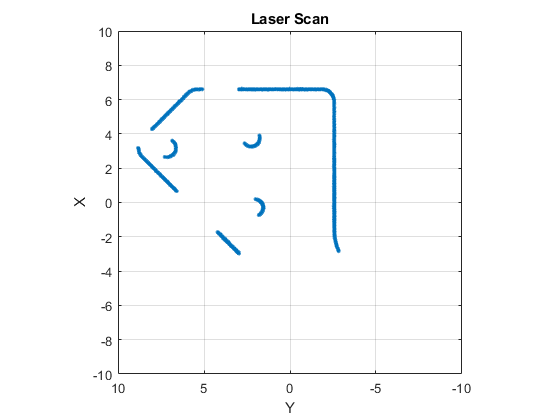

plot(laserScan)

[velPub, velMsg] = rospublisher('/vesc/high_level/ackermann_cmd_mux/input/nav_0')

velPub =   Publisher with properties:

         TopicName: '/vesc/high_level/ackermann_cmd_mux/input/nav_0'
        IsLatching: 1
    NumSubscribers: 1
       MessageType: 'ackermann_msgs/AckermannDriveStamped'


velMsg =   ROS AckermannDriveStamped message with properties:

    MessageType: 'ackermann_msgs/AckermannDriveStamped'
         Header: [1×1 Header]
          Drive: [1×1 AckermannDrive]

  Use showdetails to show the contents of the message


velMsg.Drive.Speed = 3;
send(velPub,velMsg);
pause(2);

velMsg.Drive.Speed = 0;
send(velPub,velMsg);

velMsg.Drive.Speed = -1;
send(velPub,velMsg);
pause(2);

velMsg.Drive.Speed = 0;
send(velPub,velMsg);

## Generate ROS nodes

The `ros.Node` object represents a ROS node in the ROS network. The object enables you to communicate with the rest of the ROS network. You must create a node before you can use other ROS functionality, such as publishers, subscribers, and services.

masterHost = '192.168.137.134';
Mod_pose = ros.Node('Mod_pose', masterHost);
posePub = ros.Publisher(Mod_pose,'/Mod_pose','geometry_msgs/PoseWithCovariance');

## Clear ROS node

Clear the ROS network of publisher, subscriber, and nodes. Delete the `Core` object to shut down the ROS master.

clear Mod_pose;